In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of base harmonic excitation, the stable limit cycle is perturbed as stable torus. We are interested in the persistence of the torus under the change of excitation frquency and amplitude. More details can be found in [1]

[1] M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. [https://doi.org/10.1016/j.ymssp.2022.109993](https://doi.org/10.1016/j.ymssp.2022.109993)

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

clear all;
nmodes = 4;
fcload = 1;
flowspeed = 6;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)
[F, lambda] = functionFromTensors(M, C, K, fnl);
lambda = sort(lambda);

Create dynamical system 

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *

   0.0076 + 0.1353i
   0.0076 - 0.1353i
  -0.0704 + 0.4747i
  -0.0704 - 0.4747i
  -0.1225 + 0.0190i
  -0.1225 - 0.0190i
  -0.1240 + 1.0973i
  -0.1240 - 1.0973i



Choose Master subspace (perform resonance analysis)

We take the pair of unstable modes as the master subspace and compute the corresponding 2D unstable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 9;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

sigma_out = -16
sigma_in = -16


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.80E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.18E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.48E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.16E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.74E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.82E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 6.77E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 8.35E-02 MB


%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 0.009578\,{\rho_{1}}^{9}+0.00558\,{\rho_{1}}^{7}-0.05442\,{\rho_{1}}^{5}-1.006\,{\rho_{1}}^{3}+0.7631\,\rho_{1}\\ 0.009245\,{\rho_{1}}^{8}+0.047\,{\rho_{1}}^{6}+0.1781\,{\rho_{1}}^{4}+0.5574\,{\rho_{1}}^{2}+13.53 \end{array}\right)$$

Prediction of the emergence of isola

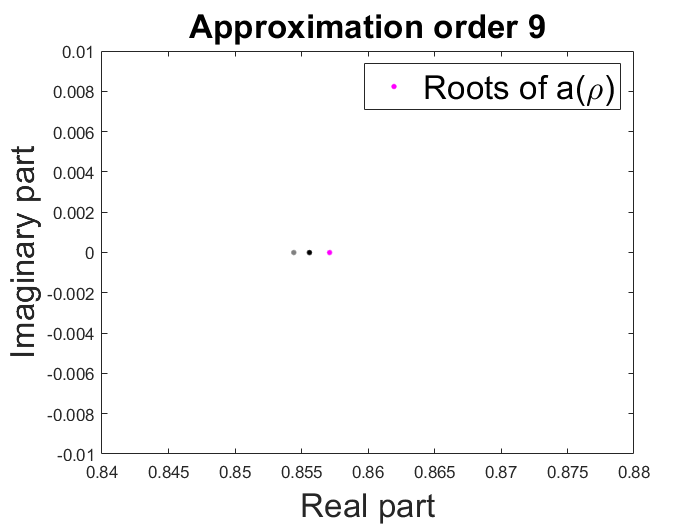

plot_analytical_domain(order,R0)
xlim([0.84 0.88]); ylim([-0.01 0.01])

we indeed see a converged root, which indicates that the system has isola under the addition of forcing. In addition, cubic approximation presents analytical prediction of the critical value of forcing amplitude for the merging of main and isola branches.

lamdM = lamdMaster(1);
gamma1 = R0(3).coeffs(1,2);
arho = sqrt(4*real(lamdM)^3/27/abs(real(gamma1)));
brho = imag(lamdM)+imag(gamma1)*real(lamdM)/3/abs(real(gamma1));
f = abs(W(1:n,1)'*fext*0.5);
epsc = arho/brho^2/f

epsc = 0.0043

Convergence of backbone curve

syms rho_1 positive
[coeffs,powers]=coeffs(y(2));
tmp = simplify(log(powers));
exp_idx = double(tmp./log(rho_1));

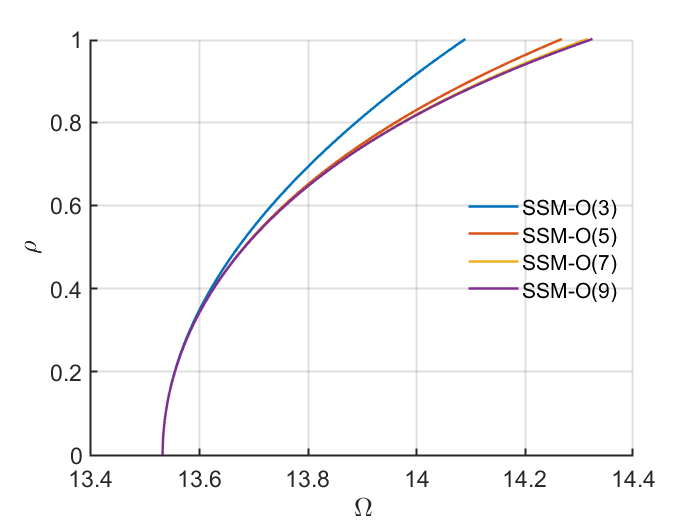

rhosamp = 0:0.01:1.0;
orders = [3 5 7 9];
plot_backbone_curves(double(coeffs),exp_idx,rhosamp,orders)

phiend = zeros(n,1);
lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
for k=1:n
   x    = 1;
   phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
        (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
   phiend(k) = phin;
end
% disp at the free end
obsfun = @(x,mapx,nmodes) mapx*x(1:nmodes,:);
obs = @(x) obsfun(x,phiend',n);

sigma_out = -16
sigma_in = -16
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.59E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.97E-02 MB
gamma = 
  -1.0056 + 0.5574i



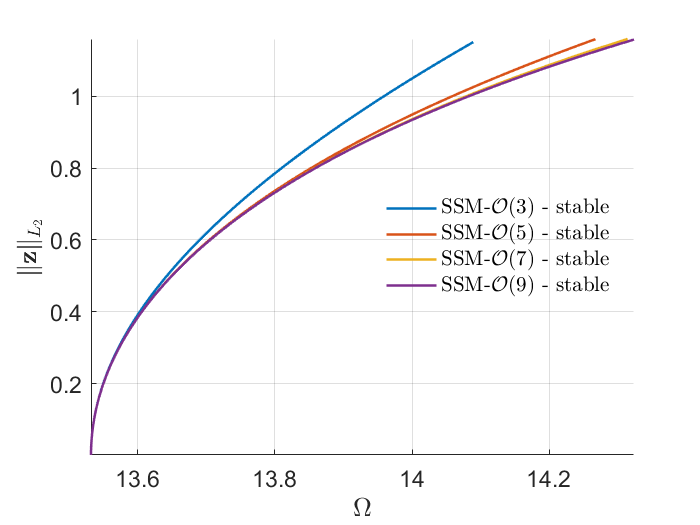

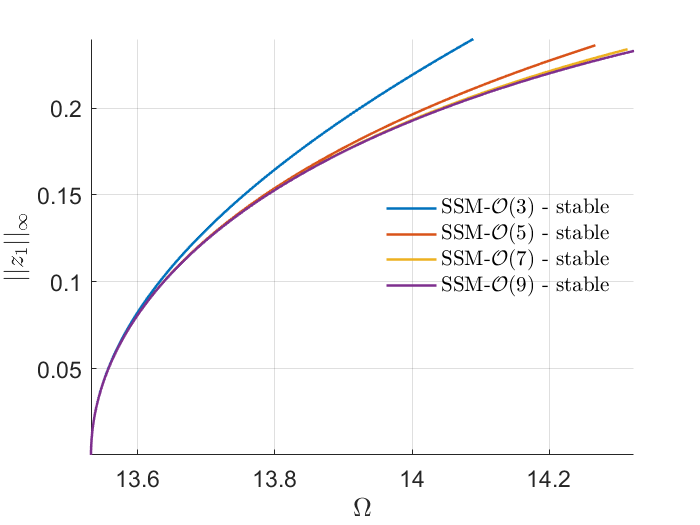

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.65E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.03E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.33E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.01E-02 MB
gamma = 
  -1.0056 + 0.5574i
  -0.0544 + 0.1781i

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.10E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.40E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.08E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.66E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at ord

%  backbone curve in physical coordiantes
set(S.FRCOptions, 'outdof',obs);
rhomax = 1;
freqrange = [0.94 1.15]*imag(D(1));
BB = S.extract_backbone(resonant_modes, freqrange, [3 5 7 9],rhomax);

### Transient response prediction

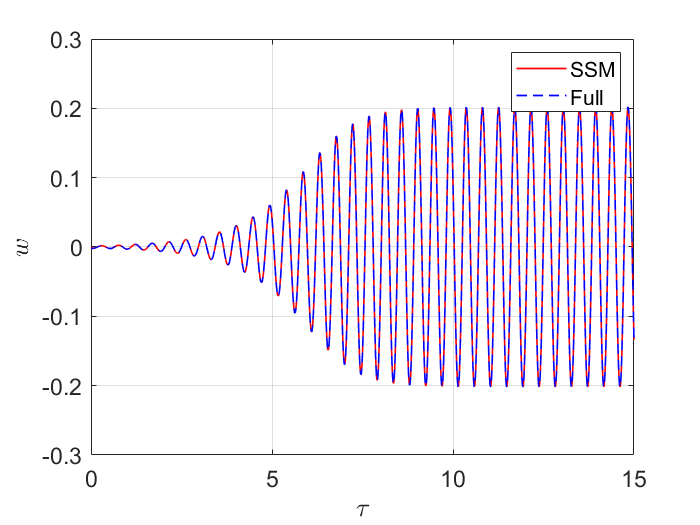

tf = 15;
nsteps = 3000;
z0    = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1) = 0.001;
outdof = [1:n n+1];
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, z0);
[tInt,zInt] = time_integration_transient(DS,0,...
    'nSteps', nsteps, 'nCycles', ceil(tf/2/pi), ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);
figure;
plot(traj.time,traj.phy(:,1:n)*phiend,'r-','LineWidth',1); hold on
plot(tInt,zInt(:,1:n)*phiend,'b--','LineWidth',1);
xlabel('$\tau$','Interpreter',"latex",'FontSize',14);
ylabel('$w$','Interpreter',"latex",'FontSize',14);
set(gca,'FontSize',14); grid on
legend('SSM','Full')
xlim([0,min(traj.time(end),tInt(end))]);

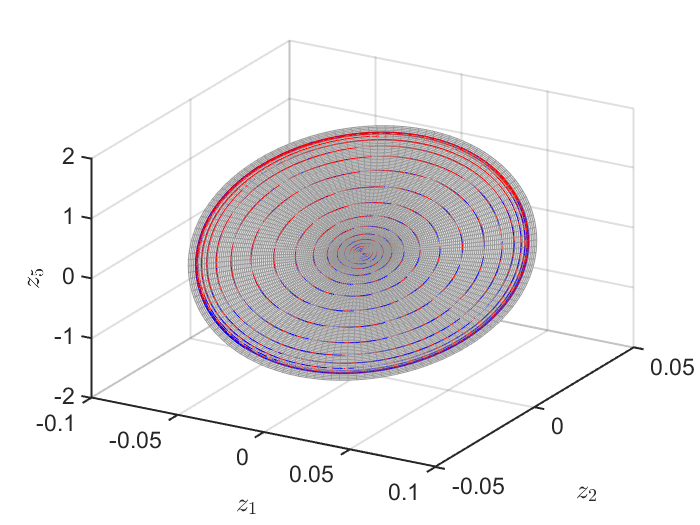


rhosamp = [0:0.01:0.9];
plotdofs = [1 2 n+1];
plot_2D_auto_SSM(W0,rhosamp,outdof(plotdofs));
view([30 30])
hold on
plot3(traj.phy(:,plotdofs(1)),traj.phy(:,plotdofs(2)),traj.phy(:,plotdofs(3)),'r-');
plot3(zInt(:,plotdofs(1)),zInt(:,plotdofs(2)),zInt(:,plotdofs(3)),'b--');

### Forced response - periodic orbit

% add Forcing
kappas = [-1; 1];
coeffs = [fext fext]/2;
epsilon = 0.0045;
DS.add_forcing(coeffs, kappas, epsilon);
set(DS.Options,'BaseExcitation',true);

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = -16
sigma_in = -16
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.65E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.03E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.33E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.01E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

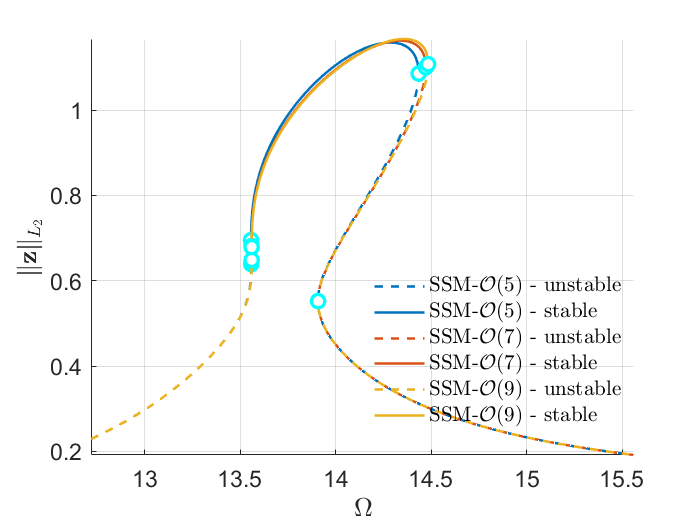

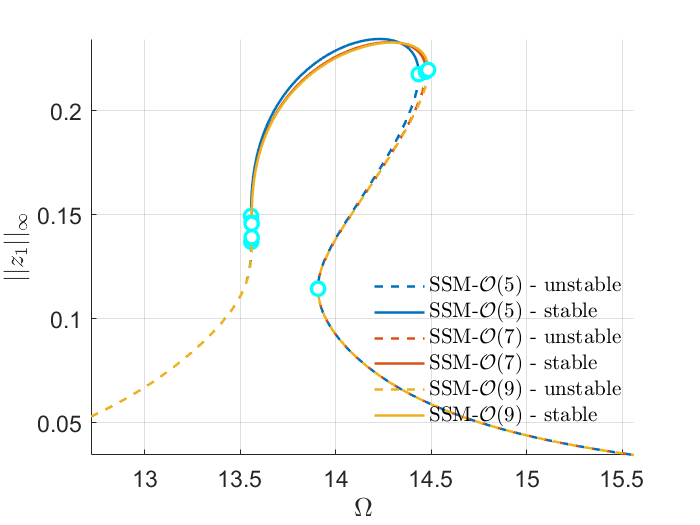

*****************************************
Calculating FRC using SSM with master subspace: [1  2]
sigma_out = -16
sigma_in = -16
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.72E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.10E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.40E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.08E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.66E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.74E-02 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance,

% set up FRC options
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.contOptions, 'PtMX', 300, 'h_max', 0.1);
set(S.FRCOptions, 'omegaSampStyle', 'cocoBD');
set(S.FRCOptions, 'outdof',obs,'method','continuation ep','p0',[]);
S.extract_FRC('freq',freqrange,[5,7,9]);


 Run='bd_ld_v6.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          7.58e-02  1.80e+01    0.0    0.0    0.0
   1   1  1.51e-01  1.59e+00  6.44e-02  1.80e+01    0.0    0.0    0.0
   2   1  1.85e-01  1.35e+00  5.24e-02  1.80e+01    0.0    0.1    0.0
   3   1  2.40e-01  1.10e+00  3.99e-02  1.80e+01    0.0    0.1    0.0
   4   1  3.36e-01  8.45e-01  2.65e-02  1.80e+01    0.0    0.1    0.0
   5   1  5.40e-01  5.67e-01  1.22e-02  1.81e+01    0.0    0.2    0.0
   6   1  1.00e+00  2.66e-01  2.29e-04  1.81e+01    0.0    0.2    0.0
   7   1  1.00e+00  6.40e-03  6.41e-08  1.81e+01    0.0    0.2    0.0
   8   1  1.00e+00  1.46e-06  3.37e-15  1.81e+01    0.0    0.3    0.0
   9   1  1.00e+00  7.47e-14  6.94e-16  1.81e+01    0.1    0.3    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         am

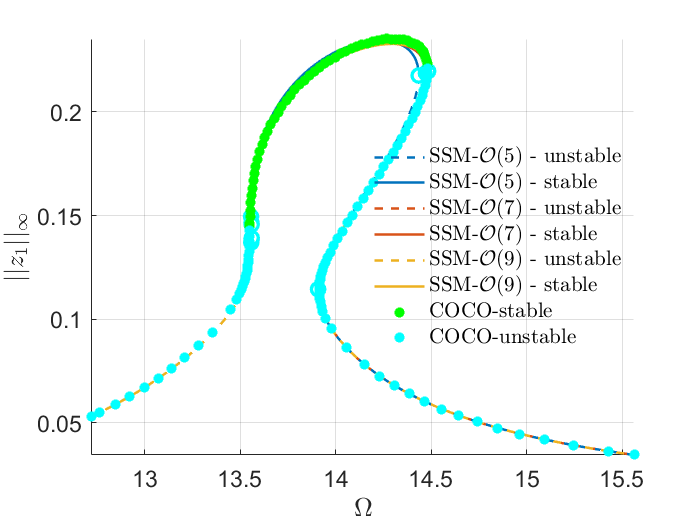

nCycles = 500;
coco = cocoWrapper(DS, nCycles, obs);
set(coco.Options, 'PtMX', 1000, 'NTST',10, 'dir_name', 'bd_ld_v6');
set(coco.Options, 'NAdapt', 2, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd_ld = coco.extract_FRC(freqrange);

timings.cocoFRCbd_ld = toc(start)

timings = struct with fields:
    cocoFRCbd_ld: 63.5071


**Exercises: you are encouraged to reproduce the results shown in [1]. Specifically, please perform the following task**

- Change the value of epsilon and see isola bifurcations

- Continuation of saddle-node bifurcated periodic orbits via SSM_ep2SN

- Continuation of torus bifurcation periodic orbits (which are Hopf fixed points of the ROM) via SSM_ep2HB

- Continuation of two-dimensional tori via SSM_HB2po etcs

- Continuation of infinite period bifurcation points via SSM_po2Tinf